# Quantum Data Communication Protection with the Quantum  Permutation Pad  Block Cipher in Counter Mode and Cliffords

**Author**: Michel Barbeau

**Date**: June 22, 2023

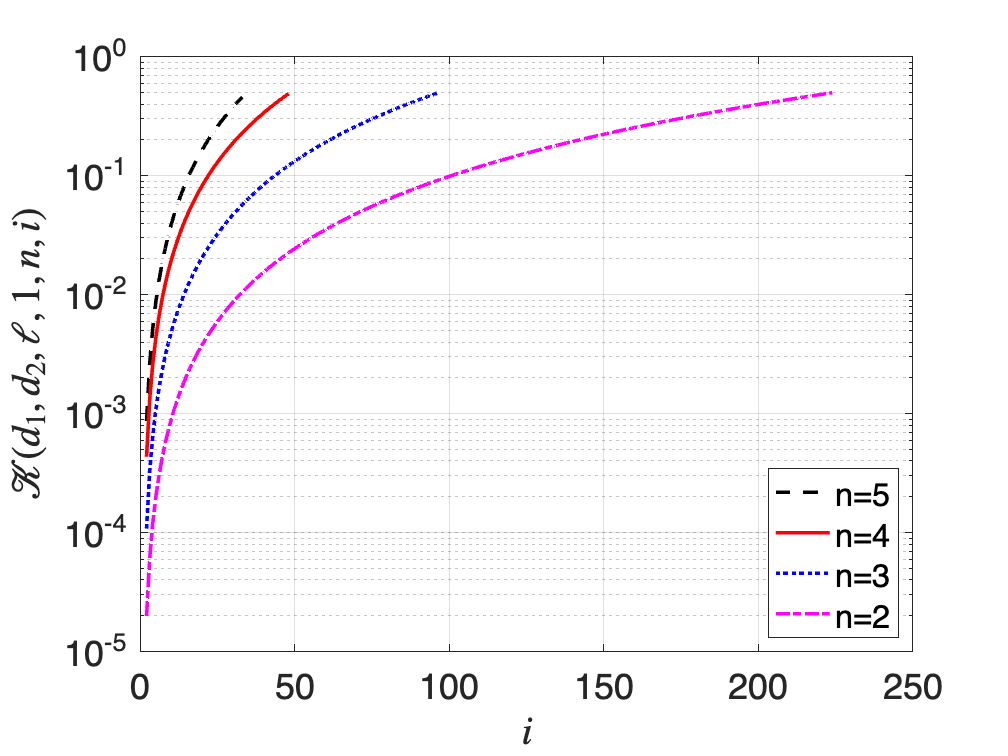

clear;
cd '/Users/michelbarbeau/Dropbox/MyLiveScripts/Block-QPP/Quantum'
n  = [  2  3 4 5 ]; % block size (bits)
d1 = [ 56 17 6 3]; % number of distinct Clifford operators
ell = 2; % number of authentications bits
d2 = [ 56 17 6 3]; % number of distinct permutations
m = [ 1 2 4 8 ]; % number of blocks
imax = @(m, n, ell, d1, d2) floor( sqrt( 2^(m*(n+ell)) * d1^m * d2^m ) );
num = @(m, n, ell, d1, d2) imax(m, n, ell, d1, d2) * (imax(m, n, ell, d1, d2) - 1);
den = @(m, n, ell, d1, d2) 2^(m*(n+ell)+1) * d1^m * d2^m;
cmax = @(m, n, ell, d1, d2) num(m, n, ell, d1, d2) / den(m, n, ell, d1, d2);
z = zeros(length(n), imax(1, n(1), ell(1), d1(1), d2(1)));
%for j=1:length(n) % loop on the number of qubits
k = 1;
for k=1:length(n)
    for i=1:imax(1, n(k), ell, d1(k), d2(k))
        z(k, i) =  i*(i-1) / den(1, n(k), ell, d1(k), d2(k));
    end;
end;
%loglog(x,low./denominator, '--k+', 'LineWidth', 2, 'MarkerSize',6);
figure;
plot(z(4,:),'--k', 'LineWidth', 2);
hold on;
plot(z(3,:),'-r', 'LineWidth', 2);
hold on;
plot(z(2,:),':b', 'LineWidth', 2);
hold on;
plot(z(1,:),'-.m', 'LineWidth', 2);
set(gca,'YScale','log')
xlabel('$i$','interpreter','latex');
ylabel('$\mathcal{K}(d_1,d_2,\ell,1,n,i)$','interpreter','latex');
set(gca,"FontSize", 20);
legend('n=5','n=4','n=3','n=2','Location','southeast');
grid on;
exportgraphics(gca,'collisionprob.png');

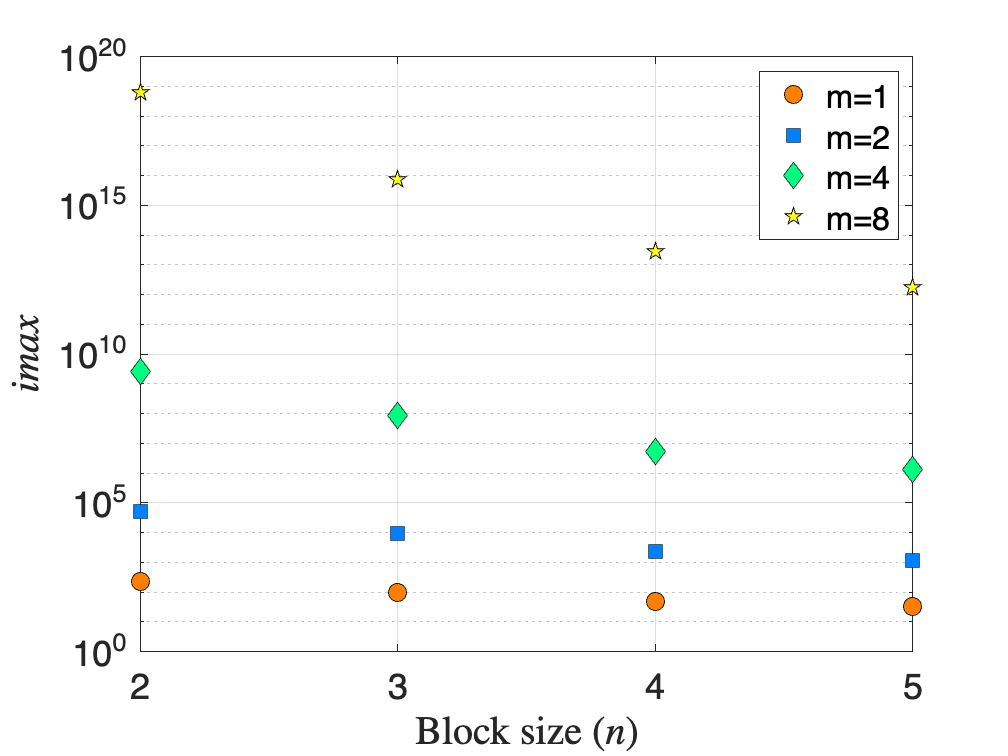

z = zeros(length(n), length(m));
for j=1:length(n) % loop on the number of qubits
    for k=1:length(m) % loop on the number of blocks
        z(j, k) = imax(m(k), n(j), ell, d1(j), d2(j));
    end;
end;
figure;
plot(n,z(:,1),'o','MarkerSize',10,'MarkerEdgeColor','black', 'MarkerFaceColor', [1 0.5 0 ]);
hold on;
plot(n,z(:,2),"square",'MarkerSize',10,'MarkerEdgeColor','black', 'MarkerFaceColor', [0 0.5 1]);
hold on;
plot(n,z(:,3),"diamond",'MarkerSize',10,'MarkerEdgeColor','black', 'MarkerFaceColor', [0 1 0.5 ]);
hold on;
plot(n,z(:,4),"pentagram",'MarkerSize',10,'MarkerEdgeColor','black', 'MarkerFaceColor', [1 1 0.1]);
legend('m=1','m=2','m=4','m=8','location','northeast');
set(gca,'YScale','log');
grid on;
xlabel('Block size ($n$)','interpreter','latex');
ax = gca;
ax.XTick = unique( round(ax.XTick) );
ylabel('$imax$','interpreter','latex');
set(gca,"FontSize", 20);
exportgraphics(gca,'cmax.png');